# Analysis Of An airfoil Using Vortex Panel Method (S1223)

data        = load('s1223.txt'); 
XB          = flip(data(:,1));
YB          = flip(data(:,2));
YB(1,1)     = 0;
YB(end,1)    = 0;

M = size(XB,1);

z = 1;
alp=0;                                      % > array of various Angle of Attacks                                      
cavg_arr=0;                                 % > array of Avg(coefficent of pressure) 
cavg=0;                                     % > Avg(coefficent of pressure)
coeff=0;                                    % > coefficent of lift
c_arr=0;                                    % > array of coefficent of lift                                  
p=0;                                             
cp_arr=0;
X=0;
Y=0;
Gama=0;
V=0;
CP1=0;
V_inf=2;                                    % > represent v infinity
CT1=0;CT2=0;CPu=0;CP=0;CN1=0;CN2=0;AT=0;AN=0;RHS=0;
theta=0;% > array of coefficent of pressure 

## Calculation of control points and other geometric parameters

alpha1 = 0;               % > Angle of Attack used for making array of various angles which is used for further analysis
alpha = 0;                % > Angle of Attack (used in inner loop for finding various parameters for a given angle)
for p = 1:40
    
    alpha1=alpha1+0.5;
    alp(p)=alpha1; %alp is the alpha array
    alpha = (alpha1) * (pi/180);
   
    for i = 1:M-1
        X(i,1)        = 0.5*( XB(i) + XB(i+1) );
        Y(i,1)        = 0.5*( YB(i) + YB(i+1) );
        S(i,1)        = sqrt( (XB(i+1)-XB(i))^2 + (YB(i+1)-YB(i))^2 );
        theta(i,1)    = atan2( (YB(i+1)-YB(i)) , (XB(i+1)-XB(i)) );
        RHS(i,1)      = sin(theta(i) - alpha);
    end

## Calculation of Coefficients

    for i = 1:M-1
        for j = 1:M-1
            if (i == j)
                CN1(i,j) = -1;
                CN2(i,j) = 1 ;
                CT1(i,j) = 0.5*pi;
                CT2(i,j) = 0.5*pi;
            else
                A = - (X(i) - XB(j))*(cos(theta(j))) - (Y(i) - YB(j))*(sin(theta(j)));
                B = (X(i) - XB(j))^2 + (Y(i) - YB(j))^2;
                C = sin(theta(i) - theta(j));
                D = cos(theta(i) - theta(j));
                E = (X(i) - XB(j))*sin(theta(j)) - (Y(i) - YB(j))*cos(theta(j));
                F = log(1 + ((S(j))^2 + (2*A*S(j))) / B);
                G = atan2((E*S(j)) , (B + A*S(j)));
                P = ((X(i) - XB(j)) * sin(theta(i) - 2*theta(j))) + ((Y(i) - YB(j)) * cos(theta(i) - 2*theta(j)));
                Q = ((X(i) - XB(j)) * cos(theta(i) - 2*theta(j))) - ((Y(i) - YB(j)) * sin(theta(i) - 2*theta(j)));
                
                CN2(i,j) = D + ((0.5*Q*F)/S(j)) - ((A*C + D*E)*(G/S(j)));
                CN1(i,j) = 0.5*D*F + C*G - CN2(i,j);
                CT2(i,j) = C + ((0.5*P*F)/S(j)) + ((A*D - C*E)*(G/S(j)));
                CT1(i,j) = 0.5*C*F - D*G - CT2(i,j);
            end
        end
    end

## Computation of Influence Coefficients

    for i = 1:M-1
        AN(i,1) = CN1(i,1);
        AN(i,M) = CN2(1,M-1);
        AT(i,1) = CT1(i,1);
        AT(i,M) = CT2(i,M-1);
        for j = 2:M-1
            AN(i,j) = CN1(i,j) + CN2(i,j-1);
            AT(i,j) = CT1(i,j) + CT2(i,j-1);
        end
    end
    AN(M,1) = 1;
    AN(M,M) = 1;
    for j = 2:M-1
        AN(M,j) = 0;
    end
    RHS(M) = 0;

## Solve for Gamma and velocity/pressure

    Gama = AN\RHS;                  % Solving for a syetem of linear equations
    
    for i = 1:M-1
        V(i) = cos(theta(i)-alpha);
        for j = 1:M
            V(i) = V(i) + AT(i,j)*Gama(j);
            CP(i) = 1 - (V(i))^2;
        end
    end
    
   


## Calculation of Lift Coefficient

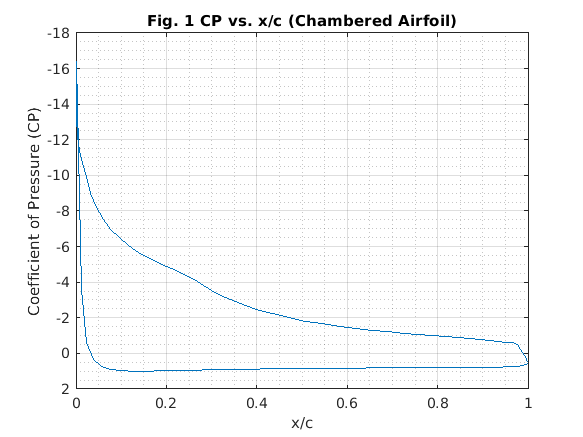

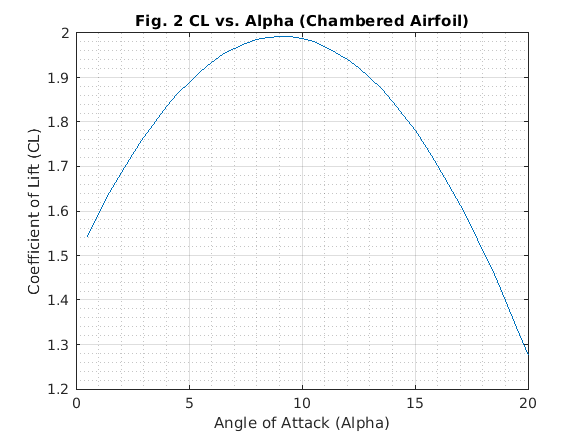

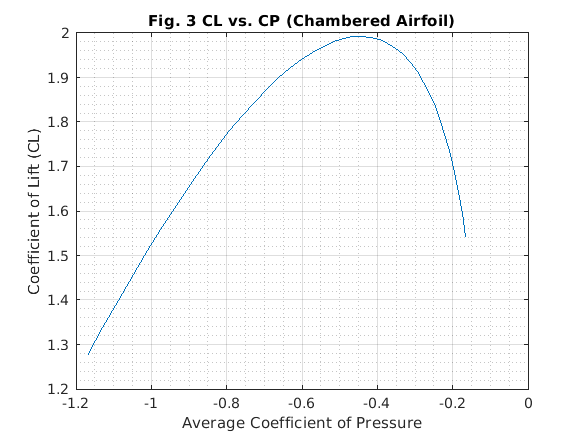

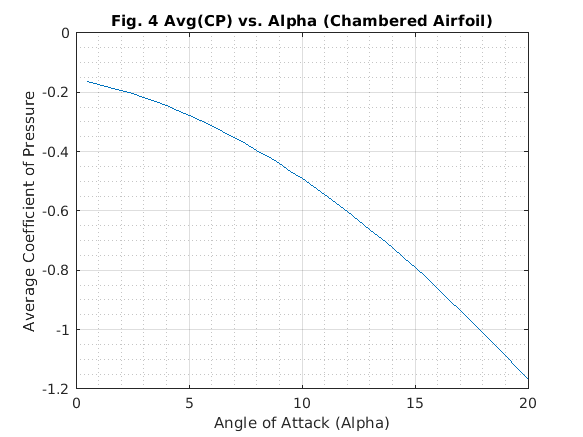

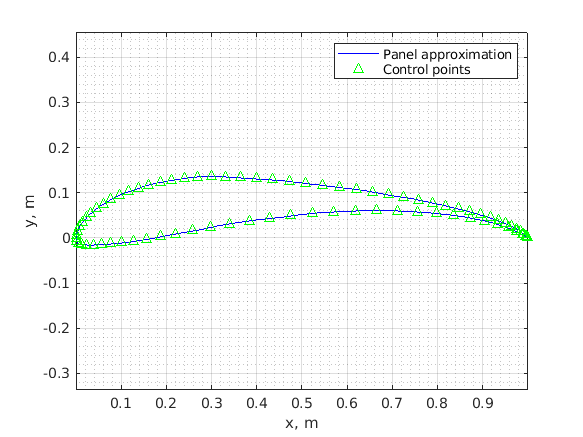

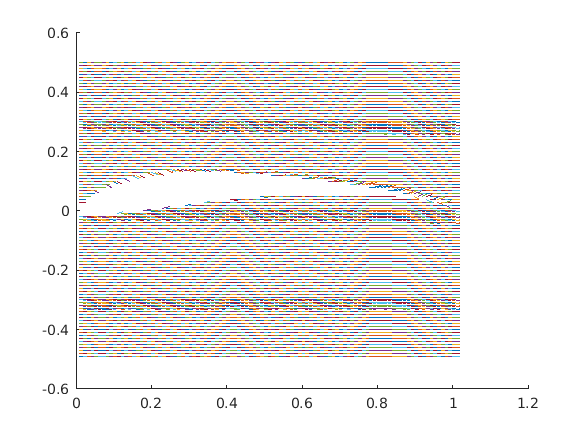

    CPl = CP(1:((M-1)/2));
    CPl = flip(CPl);
    CPu = CP((((M-1)/2)+1):end);
    
    dCP = CPl - CPu;
    dx = X((((M-1)/2)+1):end);
    ds = 0;
    j=0;
   
    coeff = trapz(dx,dCP);
    c_arr(p)=coeff;                  % > For making array of coefficient of lift
    
    % > For making array of Avg(coefficient of pressure)
    
    cavg_arr(p)=cavg;
    cavg=0;
    for j = 1:80
        cavg=cavg+CP(j);
    end
   
    cavg=cavg/160;                            % > Calculating average value of CP
    cp_arr(p)=cavg;                           % > array of Avg(CP)
end

% > PLot of CP vs. X
 figure(1)                                    
    plot(X,CP);
    set(gca,'Ydir','reverse');
    xlabel('x/c');
    ylabel('Coefficient of Pressure (CP)');
    grid on;
    grid minor;
    title('Fig. 1 CP vs. x/c (Chambered Airfoil)');

% > Plot of CL vs. Alpha
figure (2)
  plot(alp,c_arr);
  xlabel('Angle of Attack (Alpha)'); 
  ylabel('Coefficient of Lift (CL)');
  grid on;
  grid minor;
  title('Fig. 2 CL vs. Alpha (Chambered Airfoil)');
  
% > Plot of CL vs. CP
figure (3)
    plot(cp_arr,c_arr);
    xlabel('Average Coefficient of Pressure'); 
    ylabel('Coefficient of Lift (CL)');
    grid on;
    grid minor;
    title('Fig. 3 CL vs. CP (Chambered Airfoil)');

% > Plot of Avg(CP) vs. Alpha
figure (4)
  plot(alp,cp_arr);
  xlabel('Angle of Attack (Alpha)'); 
  ylabel('Average Coefficient of Pressure'); 
  grid on;
  grid minor;
  title('Fig. 4 Avg(CP) vs. Alpha (Chambered Airfoil)');

% > Plot of Airfoil
figure(5)
  plot(XB,YB,'b',X,Y,'g^'); 
  axis equal; legend('Panel approximation','Control points')
  xlabel('x, m'); ylabel('y, m'); 
  grid on;
  grid minor;



% > this code is used to plot velocity over the airfoil

for l=1:80
    ds(l)=XB(l+1)-XB(l);    %-> Represents the elemental length
end
n=80;                       %-> number of panels

thet=0;                     %-> Defining the angle between control points and point where potential is taken
scale = 0.01;

Q = zeros(101,101);

for i=0:100                 %-> This loop is used to find the potential over the surface of the airfoil
    for j=-50:50
        potential = 0;
        if 0 == inpolygon(scale*i,scale*j,X,Y)
            for k = 1:n                                 
               thet=atan((j*scale-Y(k)/(i*scale-X(k))));
               potential=potential-(1/(2*pi)).*Gama(k).*ds(k).*thet;  %-> Formula for potential
            end
        end
        Q(i+1,j+51) = potential;
    end
end
U = zeros(100, 100);                                            %-> defining the horizontal and vertical velocity
V = zeros(100, 100);

for i = 1:100
    for j = -49:50
        if 0 == inpolygon(scale*i,scale*j,X,Y)                  %-> condition to obtain all the velocity vectors outside the airfoil
            U(i,j+50) = V_inf + (Q(i+1, j+50) - Q(i, j+50))/scale;
            V(i,j+50) = (Q(i, j+51) - Q(i, j+50))/scale;
        else
            U(i,j+50) = 0;                                      %-> cancelling the velocity vectors inside the airfoil
            V(i,j+50) = 0;
        end
    end
end

figure(6)
hold on;
for i = 1:100
    for j = -49:50
        if 0 == inpolygon(scale*i,scale*j,X,Y)                  %-> plotting velocity vectors which are outside the airfoil 
            v = [U(i,j+50),V(i,j+50)];
            M = 50*norm(v);                                     %-> making the velocity vectors unit vectors to get clearer,more precise graph
            quiver(i*scale, j*scale, (U(i,j+50)/M), (V(i,j+50)/M));
        end
    end
end


